`EE 150`

`Signals and Systems`

` Lab 2 System Analysis in Time Domain`

`Date Performed: 2022/10/16`

`Class Id:Monday_1A-105`

`Name & ID:王柯皓2021533025 徐晨熙2021531046`

`1. `$y^{\prime \prime } \left(t\right)+3y^{\prime } \left(t\right)+6y\left(t\right)=6f^{\prime } \left(t\right)-8f\left(t\right),f\left(t\right)=e^{-t} u\left(t\right),y\left(0_- \right)=0,y^{\prime } \left(0_- \right)=10,y\left(0_+ \right)=0,y^{\prime } \left(0_+ \right)=6$`. Find out the zero-input response and plot it.`

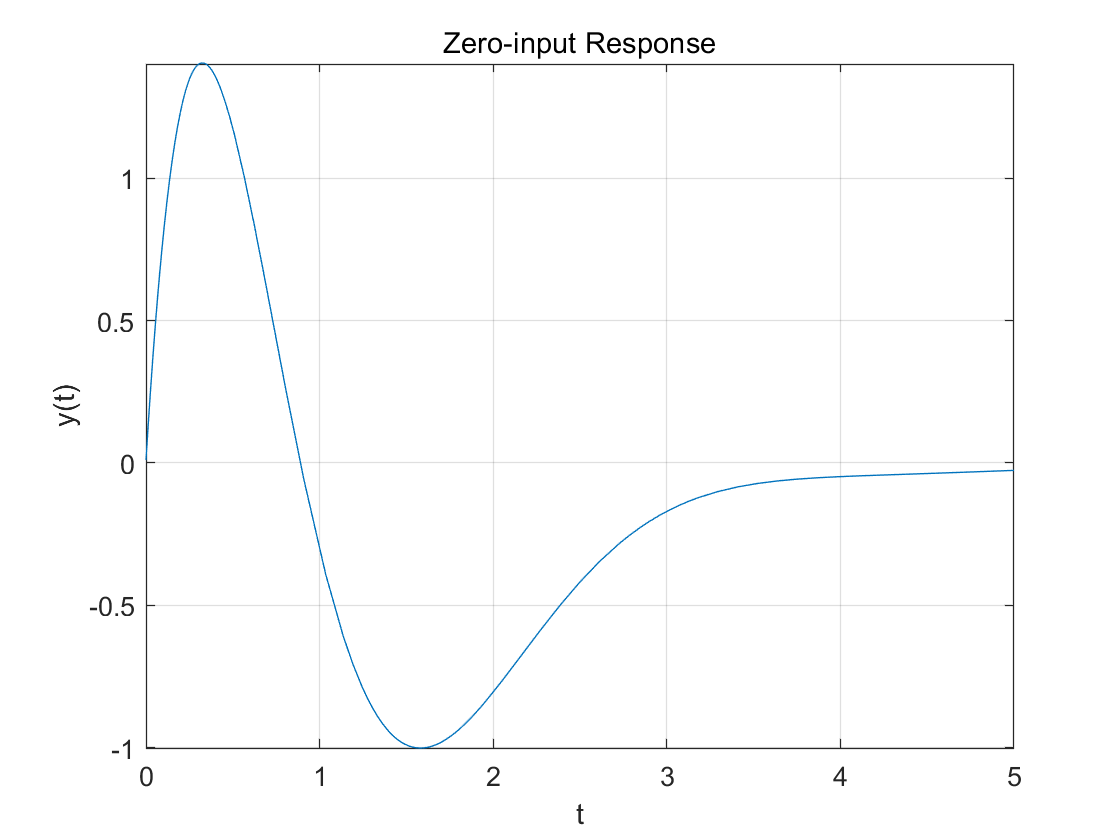

clear;
syms y(t) f(t)
D2y = diff(y,t,2);
Dy = diff(y,t);
Df = diff(f,t);
eqn1 = D2y+3*Dy+6*y==6*Df-8*f;
eqn2 = f==exp(-t).*heaviside(t);
eqns = [eqn1 eqn2];
conds = [y(-0.001)==0,Dy(-0.001)==10];
ysol = dsolve(eqns,conds);
yzi = simplify(ysol.y);
fplot(yzi,[0,5]);xlabel('t');ylabel('y(t)');title('Zero-input Response'),grid on;

`2. `$y^{\prime \prime } \left(t\right)+3y^{\prime } \left(t\right)+2y\left(t\right)=f^{\prime } \left(t\right)+3f\left(t\right),f\left(t\right)=e^{-3t} u\left(t\right)$`, find the unit impulse response with both ``impulse`` and`` lsim`` function.  Plot them in a 2*1 subplot.`

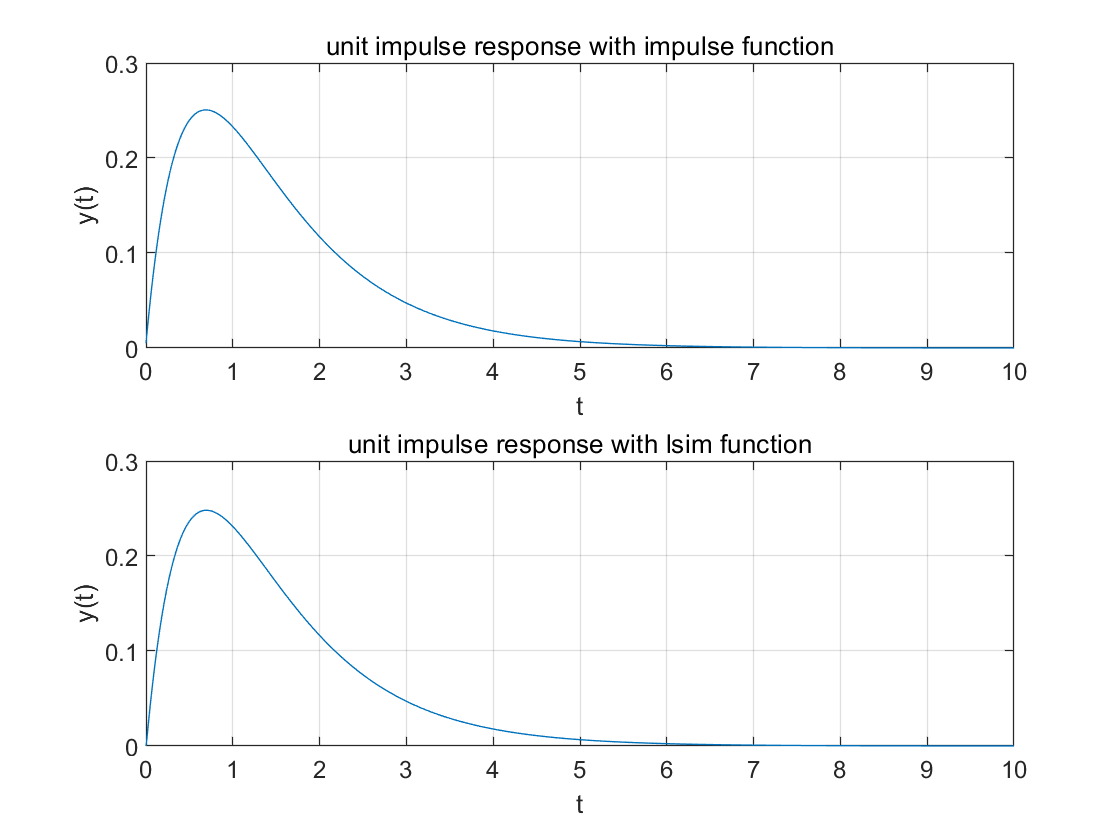

clear;clf;
dt = 0.01;
t = 0:0.01:10;
sys = tf([0 1 3],[1 3 2]);
h = impulse(sys,t);
f = exp(-3*t).*heaviside(t);
y = conv(h,f)*dt;
n = length(y);
tt = (0:n-1)*dt;
y1 = lsim(sys,f,t);
subplot(2,1,1);plot(tt,y);xlim([0 10]);
xlabel('t');ylabel('y(t)');title('unit impulse response with impulse function'),grid on;
subplot(2,1,2);plot(t,y1);ylim([0 0.3]);
xlabel('t');ylabel('y(t)');title('unit impulse response with lsim function'),grid on;

`3. `$y^{\prime \prime } \left(t\right)+4y^{\prime } \left(t\right)+4y\left(t\right)=f^{\prime } \left(t\right)+3f\left(t\right)$`, where `$f\left(t\right)=e^{-t} u\left(t\right),y\left(0_- \right)=1,y^{\prime } \left(0_- \right)=0,y\left(0_+ \right)=0,y^{\prime } \left(0_+ \right)=1$`. Find out the zero-state response by solving differential equation, using function lsim and convolution. Compare the three results by plotting their result in a 3*1 subplot.`

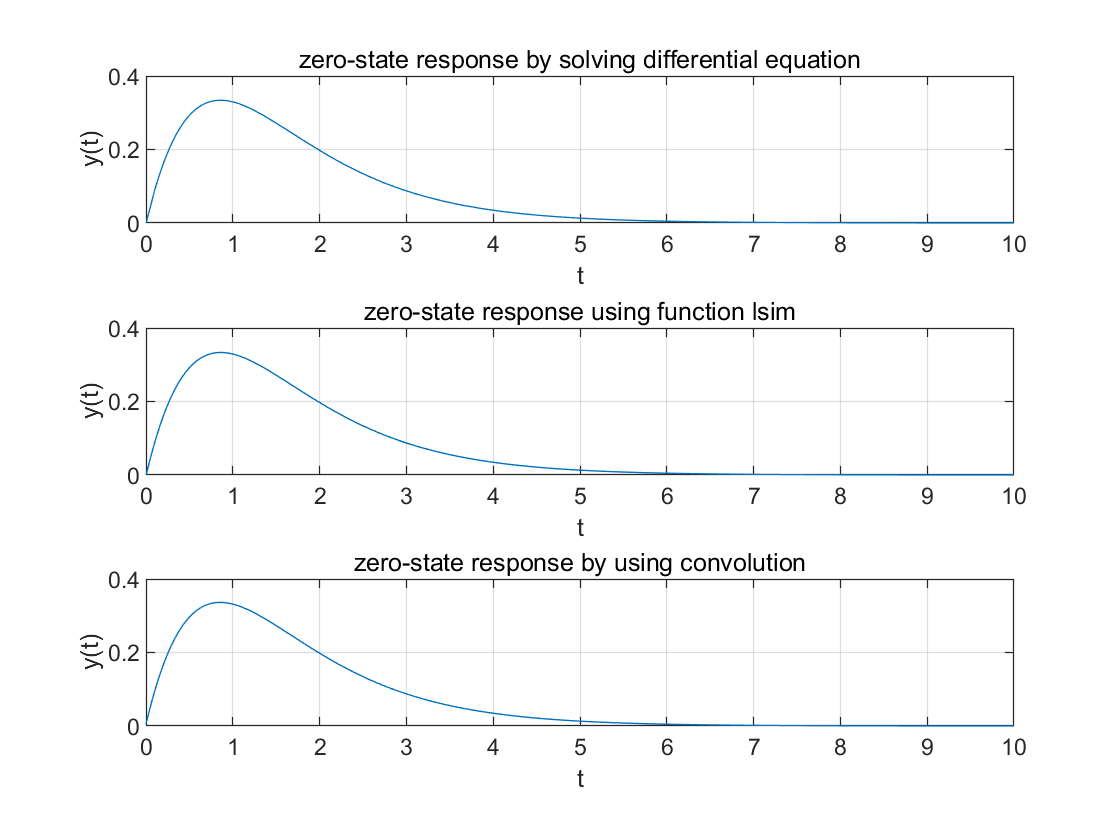

%diff
clear;clf;
syms y(t) f(t)
D2y=diff(y,t,2);
Dy=diff(y,t);
Df=diff(f,t);
eqn1=D2y+4*Dy+4*y==Df+3*f;
eqn2=f==exp(-t).*heaviside(t);
eqns=[eqn1 eqn2];
conds=[y(0.001)==0,Dy(0.001)==1];
ysol=dsolve(eqns, conds);
yzs=simplify(ysol.y);
%lsim
t=0:0.01:10;
sys=tf([0,1,3],[1,4,4]);
f=exp(-t).*heaviside(t);
y=lsim(sys,f,t);
%convolution
dt=0.01;
sys=tf([0,1,3],[1,4,4]);
h=impulse(sys,t);
y1=conv(h,f)*dt;
n=length(y1);
tt=(0:n-1)*dt;
%PLOT
subplot(3,1,1);fplot(yzs,[0,10]);ylim([0 0.4]);
xlabel('t');ylabel('y(t)');
title('zero-state response by solving differential equation'),grid on;
subplot(3,1,2);plot(t,y);
xlabel('t');ylabel('y(t)');title('zero-state response using function lsim'),grid on;
subplot(3,1,3);plot(tt,y1);xlim([0 10]);
xlabel('t');ylabel('y(t)');title('zero-state response by using convolution'),grid on;

`4. For the following circuit, `$R=3\Omega ,L=1H,C=0\ldotp 5F,x\left(t\right)=\sin \left(t\right)+\sin \left(20t\right)$`. The initial state of the circute is zero. `

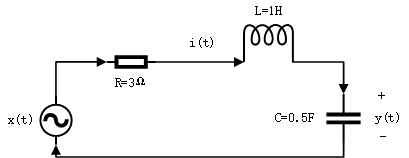

Tips: the circute can be described as:


$$\textrm{LC}\cdot y^{\prime \prime } \left(t\right)+\textrm{RC}\cdot y^{\prime } \left(t\right)+y\left(t\right)=x\left(t\right)$$


1)  `Following the tips, complete the differential equation describing the system.`

`2) Find out the full response of the system. Plot the result.`

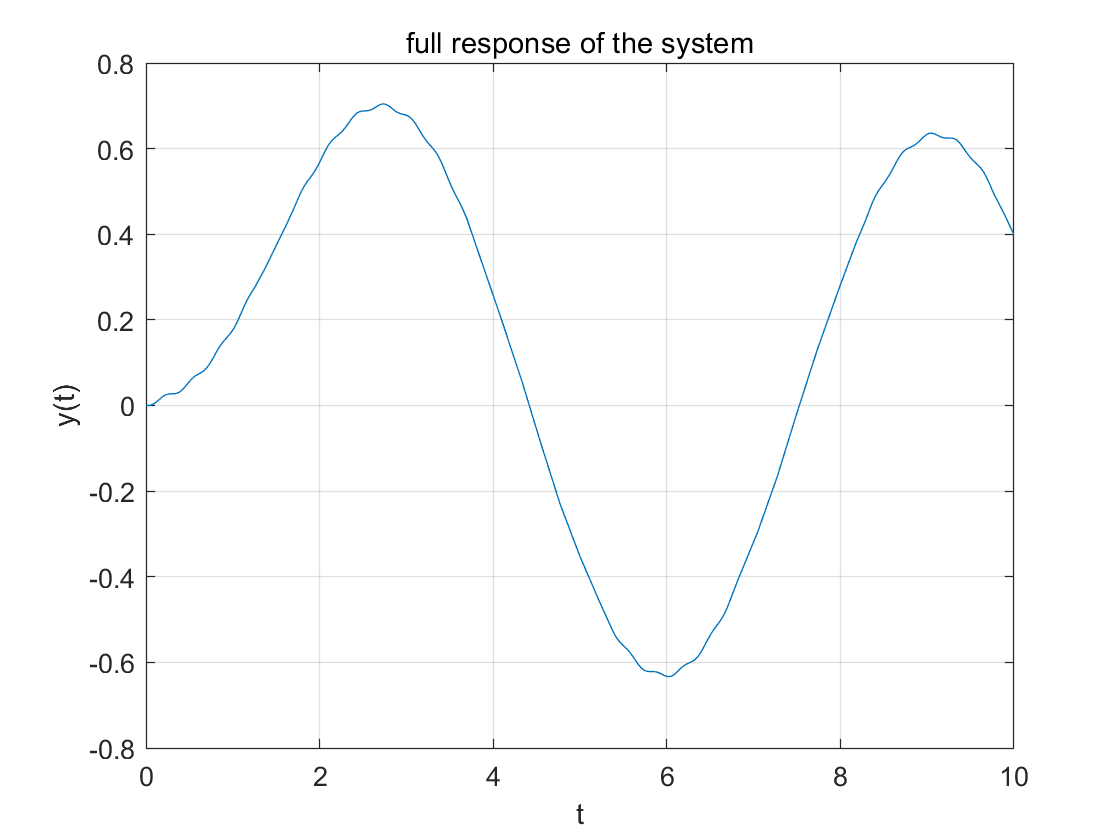

%1)
%0.5*y''(t)+1.5*y'(t)+y(t)=x(t)=sin(t)+sin(20*t)
%2)
clear;clf;
syms y(t) x(t)
D2y=diff(y,t,2);
Dy=diff(y,t);
eqn1=0.5*D2y+1.5*Dy+y==0;
conds1=[y(0)==0,Dy(0)==0];
ysol1=dsolve(eqn1,conds1);
yzi1=simplify(ysol1);
eqn2=0.5*D2y+1.5*Dy+y==sin(t)+sin(20*t);
conds2=[y(0)==0,Dy(0)==0];
ysol2=dsolve(eqn2,conds2);
yzi2=simplify(ysol2);
yzi=yzi1+yzi2;
fplot(yzi,[0 10]);ylim([-0.8 0.8]);
xlabel('t');ylabel('y(t)');title("full response of the system");grid on;

5.` Please implement the convolution function of the discrete sequence by yourself (do not use MATLAB build-in function for convolution). Use the your student ID as the inputs and display the convolution result.`

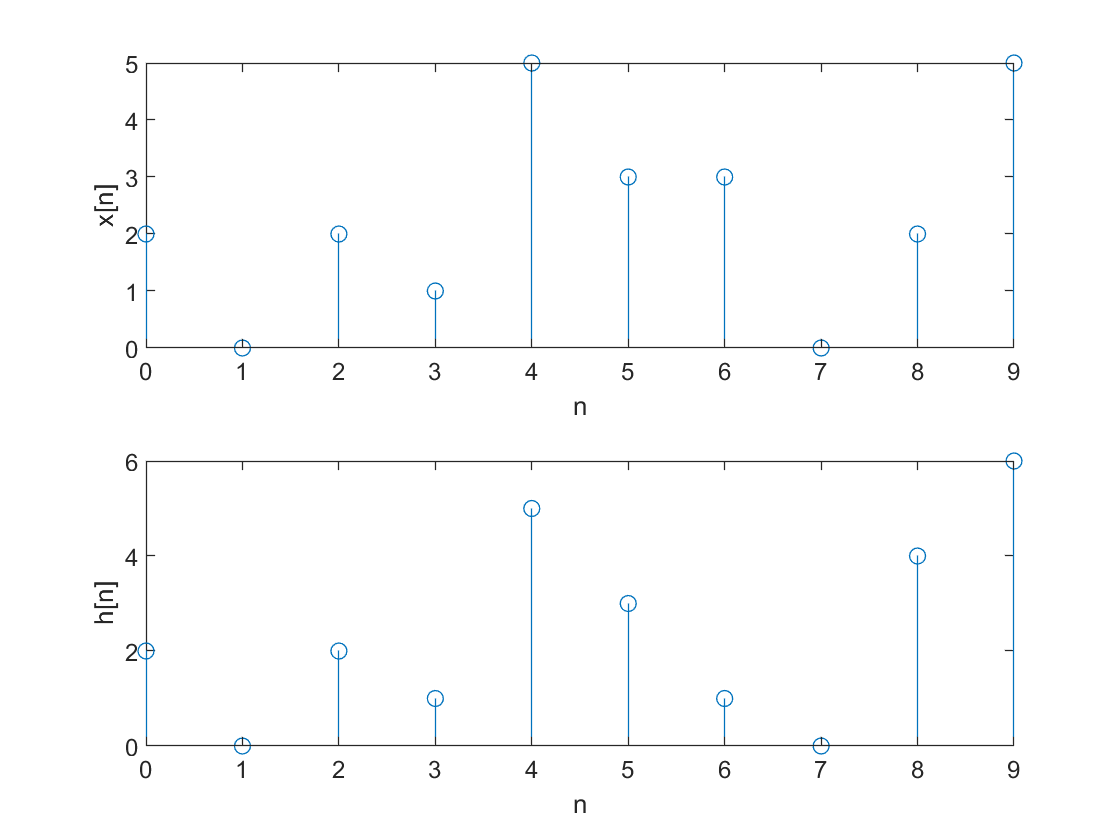

clear;
x = [2 0 2 1 5 3 3 0 2 5];
h = [2 0 2 1 5 3 1 0 4 6];
[m1,n1] = size(x);
[m2,n2] = size(h);
n3 = n1+n2-1;

xi = 0:n1-1;
hi = 0:n2-1;
yi = 0:n3-1;

figure(1)
subplot(2,1,1);
stem(xi,x);
xlabel('n');ylabel('x[n]');
subplot(2,1,2);
stem(hi,h);
xlabel('n');ylabel('h[n]');

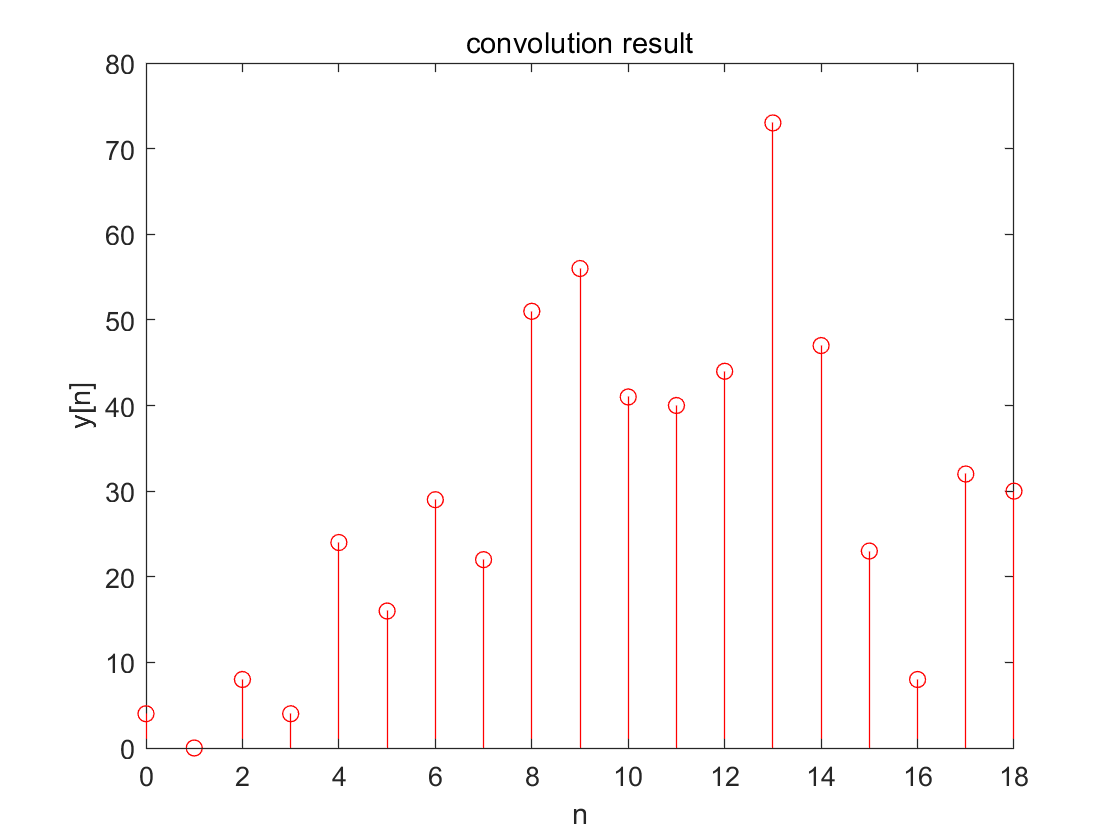

A = zeros(n3,n3);B = zeros(n3,1);C = zeros(1,n3+n3);D=zeros(1,n3);
p=fliplr(h);
B(n2:n3) = x';
C(1,1:n2) = p;
for i=1:n3
    A(i,1:n3)=C(1,1:n3);
    C=circshift(C,1);
end
Y=A*B;

figure(2)
stem(yi,Y,'r');
xlabel('n');ylabel('y[n]');title('convolution result')